# Lab. 4 - Cinemática Directa - Phantom X - ROS

- Utilice el comando SerialLink para crear el robot con los parámetros de su tabla DH:

L(1)=Link('revolute' ,'alpha', pi/2, 'a', 0, 'd', 45, 'offset', 0);
L(2)=Link('revolute' ,'alpha', 0, 'a', 105, 'd', 0, 'offset', pi/2);
L(3)=Link('revolute' ,'alpha', 0, 'a', 105, 'd', 0, 'offset', 0);
L(4)=Link('revolute' ,'alpha', 0, 'a', 75, 'd', 0, 'offset', 0);
% L(5)=Link('revolute' ,'alpha', 0, 'a', 0, 'd', 0, 'offset', 0);
Lab4b=SerialLink(L,'name','lab4')

 
Lab4b = 
 
lab4 (4 axis, RRRR, stdDH, slowRNE)                              
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         45|          0|      1.571|          0|
|  2|         q2|          0|        105|          0|      1.571|
|  3|         q3|          0|        105|          0|          0|
|  4|         q4|          0|         75|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            

%Lab4b.tool = [0 0 1 l(4); -1 0 0 0; 0 -1 0 0; 0 0 0 1];
ws = [-150 150];
q=[0 0 0 0];
Lab4b.fkine(q)

ans =     0.0000   -1.0000         0    0.0000
    0.0000    0.0000   -1.0000    0.0000
    1.0000    0.0000    0.0000  330.0000
         0         0         0    1.0000


## Conexion con Matlab:

rosinit; %Conexion con nodo maestro. Correr solo una vez despues de iniciar el .launch apropiado.

The global ROS node is already initialized and connected to the master at URI "http://localhost:11311". If you want to restart
the global node, call "rosshutdown" first.

## Script para publicar a cada topico de controlador de junta:

motorSvcClient = rossvcclient('/dynamixel_workbench/dynamixel_command'); %Creación de cliente de pose y posición
motorCommandMsg = rosmessage(motorSvcClient); %Creación de mensaje
q = [-45 45 45 60 90];  % Vector de angulos objetivo para cada motor en grados
motorCommandMsg.AddrName = "Goal_Position";
ID=5;   % Cambiar el valor de ID de 1 a 5 para seleccionar la junta a controlar.
motorCommandMsg.Id = ID;  % Asignar el Id del motor de la junta seleccionada.
motorCommandMsg.Value = round(mapfun(q(ID),-150,150,0,1023)); % Convierte los grados al valor de 10bits
if (motorCommandMsg.Value>=0 && motorCommandMsg.Value<=1023) % Verificar los limites y enviar el mensaje
    call(motorSvcClient,motorCommandMsg);
    pause(1);
end

## Suscribirse al topico de la simulacion del Phantom X

%rostopic list  % Revisamos los topicos activos, en este caso nos interesa /dynamixel_workbench/joint_states 
%rostopic type /dynamixel_workbench/joint_states  % Revisamos el tipo de mensaje del topico 
poseSub = rossubscriber("/dynamixel_workbench/joint_states","sensor_msgs/JointState"); %Creamos el publicador
pause(0.5);
jointsmsg = receive(poseSub); % Inicia la recepcion del mensaje del suscriptor
pause(0.5); 
for i=1:length(jointsmsg.Position) %Ciclo para imprimir el nombre de cada junta y su valor en radianes
    disp(jointsmsg.Name(i) + " : " + jointsmsg.Position(i))
end

## MATLAB + ROS + Toolbox:

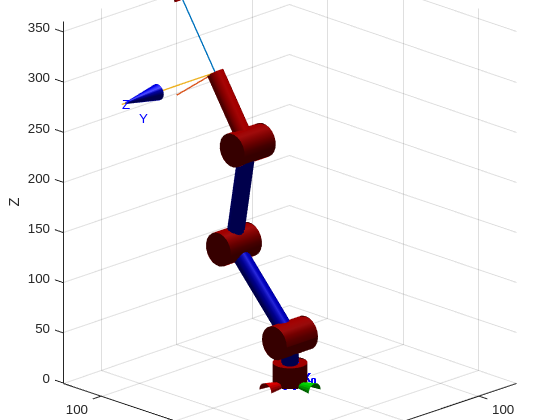

q1 = [0 0 0 0 0];
q2 = [-20, 20, -20, 20, 0]*pi/180;
q3 = [30, -30, 30, -30, 0]*pi/180;
q4 = [-90, 15, -55, 17, 0]*pi/180;
q5 = [-90, 45, -55, 45, 10]*pi/180;

q=q5;
Lab4b.plot(q(1:4))
hold on
trplot(eye(4),'rgb','arrow','length',15,'frame','0')
axis([repmat(ws,1,2) 0 360])
view(-45,20)
hold off %Cambiar la q para seleccionar cada posicion objetivo!

motorSvcClient = rossvcclient('/dynamixel_workbench/dynamixel_command'); %Creación de cliente de pose y posición
motorCommandMsg = rosmessage(motorSvcClient); %Creación del mensaje
motorCommandMsg.AddrName = "Goal_Position"; 
for i=1:length(q) %Ciclo for para enviar los 5 mensajes de posicion a los motores de manera consecutiva.
    motorCommandMsg.Id = i;
    output = (q(i)*180/pi+150)*1023/300;
    motorCommandMsg.Value = round(output);
    if (motorCommandMsg.Value>=0 && motorCommandMsg.Value<=1023) % Verificar los limites y enviar el mensaje
        call(motorSvcClient,motorCommandMsg);
        pause(1);
    end
end

% This function is a copy of the "map" function used in Arduino code.
% It takes an input value mapped from a min and max possible value and
% scales it to a desired output min and max.
%
% [output] = mapfun(value,fromLow,fromHigh,toLow,toHigh)
% value: can be a scalar entry or a matrix of values
% fromLow: lowest possible input value
% fromHigh: highest possible input value
% toLow: lowest desired output value
% toHigh: highest possible output value
% [output]: output matrix of same size as value
% 
% examples:
% output = mapfun(-.3,-1,1,0,5)
% output =
%
%    1.7500
%
% output = mapfun([-1 1 -.5 .5],-1,1,0,5)
% output =
%
%         0    5.0000    1.2500    3.7500
%
% Created by David Coventry on 1/19/2017

function output = mapfun(value,fromLow,fromHigh,toLow,toHigh)
narginchk(5,5)
nargoutchk(0,1)
output = (value - fromLow) .* (toHigh - toLow) ./ (fromHigh - fromLow) + toLow;
end